clear all;
offset = 2000

offset = 2000

Fs = 20000;    % 20 kHz sampling frequency
dt = 1/Fs;     % Sample time
Td = 1;        % Time duration of the captured audio signal - 1 sec
time = [0:dt:(Td-dt)];    % Time array
time = time(1,offset:end)

time =     0.1000    0.1000    0.1001    0.1001    0.1002    0.1002    0.1003    0.1003    0.1004    0.1004    0.1005    0.1005    0.1006    0.1006    0.1007    0.1007    0.1008    0.1008    0.1009    0.1009    0.1009    0.1010    0.1011    0.1011    0.1012    0.1012    0.1013    0.1013    0.1014    0.1014    0.1014    0.1015    0.1016    0.1016    0.1017    0.1017    0.1018    0.1018    0.1019    0.1019    0.1019    0.1020    0.1021    0.1021    0.1022    0.1022    0.1023    0.1023    0.1024    0.1024


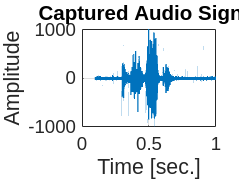


fid = fopen('distorted.bin'); % file should be in the working directory
dataHello = fread(fid,inf,'uint16'); % put 'float' instead of int if your data is float type.
fclose(fid);

dataHello = dataHello(offset:end,1);

dataHello = dataHello - mean(dataHello);   % Get rid off DC offset

figure; 
plot(time,dataHello,'LineWidth',1);

set(gca,'FontSize',14)
grid on;
xlabel('Time [sec.]','FontSize',16);
ylabel('Amplitude','FontSize',16);  
title('Captured Audio Signal');  % This is the title of the plot (modify for each different plot)



[freq spectrum]=calculateFFT(dataHello,Fs);

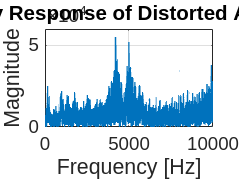


figure; 
plot(freq,spectrum,'LineWidth',1);

set(gca,'FontSize',14)
grid on;
xlabel('Frequency [Hz]','FontSize',16);
ylabel('Magnitude','FontSize',16);  
title('Frequency Response of Distorted Audio Signal');  % This is the title of the plot (modify for each different plot)

fid = fopen('Lab7_HelloAlien.bin'); % file should be in the working directory
dataHelloAlien = fread(fid,inf,'uint16'); % put 'float' instead of int if your data is float type.

Error using fread
Invalid file identifier. Use fopen to generate a valid file identifier.

fclose(fid);

dataHelloAlien = dataHelloAlien - mean(dataHelloAlien);   % Get rid off DC offset

figure; 
plot(time(3:end),dataHelloAlien(3:end),'LineWidth',1);     % Exclude the first two samples to avoid seeing large peak at the beginning of the signal

set(gca,'FontSize',14)
grid on;
xlabel('Time [sec.]','FontSize',16);
ylabel('Amplitude','FontSize',16);  
title('Captured Audio Signal with Alien Effect');  % This is the title of the plot (modify for each different plot)


[freq spectrum]=calculateFFT(dataHelloAlien(3:end),Fs);

figure; 
plot(freq,spectrum,'LineWidth',1);

set(gca,'FontSize',14)
grid on;
xlabel('Frequency [Hz]','FontSize',16);
ylabel('Magnitude','FontSize',16);  
title('Frequency Response of Audio Signal with Alien Effect');  % This is the title of the plot (modify for each different plot)

% Play the recorded sound - Hello
y = dataHello/max(dataHello);   % Normalize the sample values not to cause distortion at the audio out
sound(y,Fs);

% Play the recorded sound - Allien Hello
y2 = dataHelloAlien(3:end)/max(dataHelloAlien(3:end));   % Normalize the sample values not to cause distortion at the audio out
sound(y2,Fs);